## Project II: RANSAC

The goal of this project is to extend your RANSAC implementation from Lab 3 to improve both the quality of the returned solution as well as the run-time.

clear all
clc
addpath('./Ransac_algo' );
addpath('./functions');
warning('off','all')

### Experiment n°1: testing RANSAC without local optimization for d = 0, ..., 3

In this section, we will run RANSAC with the Td,d test for d = 0, ..., 3.

To account for RANSAC's random nature, we will repeat the experiments 10 times and report average values for the number of iterations and  run-times.

#### Experimental Evaluation

In this section:

- epsilon: probability of inliers

- eta: buond on probability of picking at least one outlier.

- threshold: value of the threshold for inlier.

- d: number of correspondences in test Td,d

#### Fixed Parameters

eta = 0.001;    % probability of picking at least one outlier
std = 1;        % standard deviation for the Gaussian Noise


#### Algorithm

for d = 0:3
    
    for outlier_ratio = 0.0:0.1:0.9
        
        % Cleaning the loop variable to avoid overwriting
        clear tStart tEnd iterations
        
        % Creation of a test case with given outlier ratio and stardard deviation
        [pts, pts_tilde, ~,~] = affine_test_case_outlier(outlier_ratio,std);
        
        % RANSAC Parameters
        threshold = outlier_ratio*100+10;
        inlier_ratio = 1-outlier_ratio;
        
        for experiment = 1:10
            
            % RANSAC algorithm
            tStart(experiment) = tic;
            [~,~,iterations(experiment)] = ransac_T(pts, pts_tilde, threshold,inlier_ratio,eta,d);
            tEnd(experiment) = toc(tStart(experiment));
            
        end
        
        % Evaluating the mean over the 10 experiments
        j = floor(outlier_ratio*10+1);
        tEnd_mean(d+1,j) = sum(tEnd)/10; % Run-time
        iterations_mean(d+1,j) = ceil(sum(iterations)/10); % N° of iterations
        
    end
end

#### Plotting figures

In the first one we will plot the number of RANSAC iterations taken while in the second one the run-time of RANSAC will be displayed.

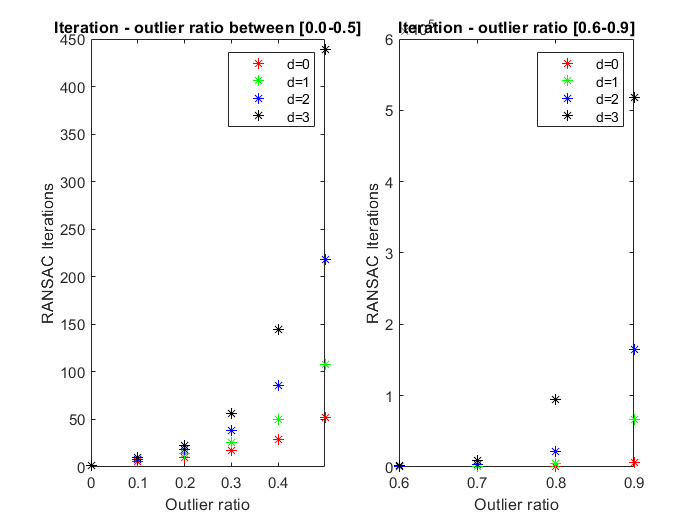

% The plots will be divided into tuo subplot. The y axis of each subplot:
y1 = [0.0:0.1:0.5];
y2 = [0.6:0.1:0.9];

% RANSAC iteration with Td,d test for different outlier ratios
figure('Name','Iterations')
subplot 121
plot(y1,iterations_mean(1,1:6),'r*',y1,iterations_mean(2,1:6),'g*',y1,iterations_mean(3,1:6),'b*',y1,iterations_mean(4,1:6),'k*')
xlabel('Outlier ratio'), xlim([0.0 0.5])
ylabel('RANSAC Iterations')
legend('d=0','d=1','d=2','d=3')
title('Iteration - outlier ratio between [0.0-0.5]')
subplot 122
plot(y2,iterations_mean(1,7:10),'r*',y2,iterations_mean(2,7:10),'g*',y2,iterations_mean(3,7:10),'b*',y2,iterations_mean(4,7:10),'k*')
xlabel('Outlier ratio')
ylabel('RANSAC Iterations')
legend('d=0','d=1','d=2','d=3')
title('Iteration - outlier ratio [0.6-0.9]')

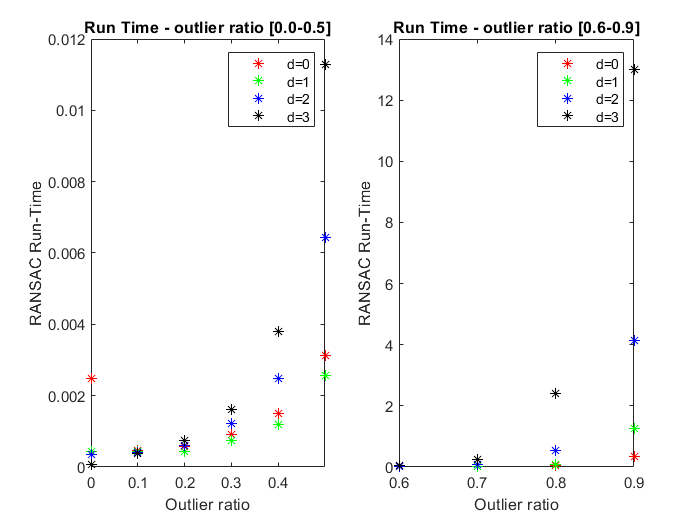


% RANSAC Run-Time with Td,d test for different outlier ratios
figure('Name','Run-Time')
subplot 121
plot(y1,tEnd_mean(1,1:6),'r*',y1,tEnd_mean(2,1:6),'g*',y1,tEnd_mean(3,1:6),'b*',y1,tEnd_mean(4,1:6),'k*')
xlabel('Outlier ratio'), xlim([0.0 0.5])
ylabel('RANSAC Run-Time')
legend('d=0','d=1','d=2','d=3')
title('Run Time - outlier ratio [0.0-0.5]')
subplot 122
plot(y2,tEnd_mean(1,7:10),'r*',y2,tEnd_mean(2,7:10),'g*',y2,tEnd_mean(3,7:10),'b*',y2,tEnd_mean(4,7:10),'k*')
xlabel('Outlier ratio')
ylabel('RANSAC Run-Time')
legend('d=0','d=1','d=2','d=3')
title('Run Time - outlier ratio [0.6-0.9]')

### Experiment n°2: With or Without local optimization

In this section we will evaluate RANSAC algorithm with T1,1. We will do this both with and without a local optimization.

Like in experiment n°1, we will use different outlier ratios. Now the range for the outlier ratio is between 0.0 and 0.6.

clear all
clc

#### Fixed parameter

d = 1;          % parameters for the Td,d test
std = 1;        % standard deviation for the Gaussian Noise
eta = 0.001;    % probability of picking at least one outlier

#### Testing with different outlier ratios

for outlier_ratio = 0.0:0.1:0.6
    
    % Cleaning the loop variable to avoid overwriting
    clear tStart tEnd iterations n_inliers avg_res
    clear tStart_best tEnd_best iterations_best n_inliers_best avg_res_best
    
    % Creation of a test case with given outlier ratio and stardard deviation
    [pts, pts_tilde, A_true, t_true] = affine_test_case_outlier(outlier_ratio,std);
    
    % RANSAC Parameters
    epsilon = 1-outlier_ratio;
    threshold = outlier_ratio*100+20;
        
    for experiment = 1:10
    
        % Without local optimization
        tStart(experiment) = tic;
        [A,t,iterations(experiment)] = ransac_T(pts, pts_tilde, threshold,epsilon,eta,d);
        tEnd(experiment) = toc(tStart(experiment));
        [n_inliers(experiment),avg_res(experiment)] = residual_evaluation(A,t,pts,pts_tilde,threshold);
        
        % With local optimization
        tStart_LO(experiment) = tic;
        [A_best,t_best,iterations_LO(experiment)] = ransac_LO(pts, pts_tilde, threshold,epsilon,eta,d);
        tEnd_LO(experiment) = toc(tStart_LO(experiment));
        [n_inliers_LO(experiment),avg_res_LO(experiment)] = residual_evaluation(A_best,t_best,pts,pts_tilde,threshold);
    end
    
    % Evaluating the mean over the 10 experiments
    k = floor(outlier_ratio*10+1);
    runtime_mean(k) = sum(tEnd)/10;                         % Run-Time without LO
    iterations_mean(k) = ceil(sum(iterations)/10);          % N° of iterations without LO
    n_inliers_mean(k) = ceil(sum(n_inliers)/10);            % N° of inliers without LO
    avg_res_mean(k) = sum(avg_res)/10;                      % Average residual without LO
    
    runtime_LO_mean(k) = sum(tEnd_LO)/10;                   % Run-Time with LO
    iterations_LO_mean(k) = ceil(sum(iterations_LO)/10);    % N° of iterations with LO
    n_inliers_LO_mean(k) = ceil(sum(n_inliers_LO)/10);      % N° of inliers with LO
    avg_res_LO_mean(k) = sum(avg_res_LO)/10;                % Average residual with LO
end

#### Results and comparison of the two tests

OutlierRatio = ["Outlier Ratio = 0.0";"Outlier Ratio = 0.1";"Outlier Ratio = 0.2";"Outlier Ratio = 0.3";"Outlier Ratio = 0.4";"Outlier Ratio = 0.5";"Outlier Ratio = 0.6"];
T = table(OutlierRatio,runtime_mean',runtime_LO_mean',iterations_mean',iterations_LO_mean',n_inliers_mean',n_inliers_LO_mean',avg_res_mean',avg_res_LO_mean');

T.Properties.VariableNames = {'Outlier Ratio' 'RunTime_No_LO' 'RunTime_Yes_LO' 'Niterations_No_LO' 'Niterations_Yes_LO' 'Ninliers_No_LO' 'Ninliers_Tes_LO' 'Avg_No_LO' 'Avg_Yes_LO'}

T = 7×9 table
        Outlier Ratio        RunTime_No_LO    RunTime_Yes_LO    Niterations_No_LO    Niterations_Yes_LO    Ninliers_No_LO    Ninliers_Tes_LO    Avg_No_LO    Avg_Yes_LO
    _____________________    _____________    ______________    _________________    __________________    ______________    _______________    _________    __________

    "Outlier Ratio = 0.0"      0.0024858         0.0034221               2                    2                 1000              1000           3.9944        1.4549  
    "Outlier Ratio = 0.1"     0.00056147        0.00098639               7                    2                  900               900           3.1128        1.4588  
    "Ou

### Experiment n°3: Different standard deviation

In this section we will evaluate RANSAC algorithm with T1,1. We will do this both with and without a local optimization.

Unlike previous experiment, now we have a fixed value of the outlier ratio ( 0.4 ) and we will use different standard deviation for the Gaussian Noise.

clear all
clc

#### Fixed parameter

d = 1;                              % parameters for the Td,d test
eta = 0.001;                        % probability of picking at least one outlier

outlier_ratio = 0.4;                % probability of outliers
epsilon = 0.95-outlier_ratio;       % probability of inliers
threshold = outlier_ratio*100+20;   % threshold for evaluating inliers and outliers

#### Testing with different standard deviation on Gaussian Noise

% loop variable
k = 1;

for std = [0.5,1,2,4,8,16]
    
    % Cleaning the loop variable to avoid overwriting
    clear tStart tEnd iterations n_inliers avg_res
    clear tStart_best tEnd_best iterations_best n_inliers_best avg_res_best
    
    % Creation of a test case with given outlier ratio and stardard deviation
    [pts, pts_tilde, A_true, t_true] = affine_test_case_outlier(outlier_ratio,std);
        
    for experiment = 1:10
    
        % Without local optimization
        tStart(experiment) = tic;
        [A,t,iterations(experiment)] = ransac_T(pts, pts_tilde, threshold,epsilon,eta,d);
        tEnd(experiment) = toc(tStart(experiment));
        [n_inliers(experiment),avg_res(experiment)] = residual_evaluation(A,t,pts,pts_tilde,threshold);
        
        % With local optimization
        tStart_LO(experiment) = tic;
        [A_best,t_best,iterations_LO(experiment)] = ransac_LO(pts, pts_tilde, threshold,epsilon,eta,d);
        tEnd_LO(experiment) = toc(tStart_LO(experiment));
        [n_inliers_LO(experiment),avg_res_LO(experiment)] = residual_evaluation(A_best,t_best,pts,pts_tilde,threshold);
    end
    
    % Evaluating the mean over the 10 experiments
    runtime_mean(k) = sum(tEnd)/10;                         % Run-Time without LO
    iterations_mean(k) = ceil(sum(iterations)/10);          % N° of iterations without LO
    n_inliers_mean(k) = ceil(sum(n_inliers)/10);            % N° of inliers without LO
    avg_res_mean(k) = sum(avg_res)/10;                      % Average residual without LO
    
    runtime_LO_mean(k) = sum(tEnd_LO)/10;                   % Run-Time with LO
    iterations_LO_mean(k) = ceil(sum(iterations_LO)/10);    % N° of iterations with LO
    n_inliers_LO_mean(k) = ceil(sum(n_inliers_LO)/10);      % N° of inliers with LO
    avg_res_LO_mean(k) = sum(avg_res_LO)/10;                % Average residual with LO
    
    k = k+1;
end

#### Results and comparison of the two tests

Std = ["Std = 0.5";"Std = 1";"Std = 2";
            "Std = 4";"Std = 8";"Std = 16"];
T = table(Std,runtime_mean',runtime_LO_mean',iterations_mean',iterations_LO_mean',n_inliers_mean',n_inliers_LO_mean',avg_res_mean',avg_res_LO_mean');
T.Properties.VariableNames = {'Standard Deviation' 'RunTime_No_LO' 'RunTime_Yes_LO' 'Niterations_No_LO' 'Niterations_Yes_LO' 'Ninliers_No_LO' 'Ninliers_Tes_LO' 'Avg_No_LO' 'Avg_Yes_LO'}

T = 6×9 table
    Standard Deviation    RunTime_No_LO    RunTime_Yes_LO    Niterations_No_LO    Niterations_Yes_LO    Ninliers_No_LO    Ninliers_Tes_LO    Avg_No_LO    Avg_Yes_LO
    __________________    _____________    ______________    _________________    __________________    ______________    _______________    _________    __________

       "Std = 0.5"          0.0041408         0.0028848             50                     9                 600                541           2.3467        3.4042  
       "Std = 1"            0.0016771          0.001003             50                     8                 600                600           4.7731        1.4907  
       "Std = 2"   